clear; clc;

As = 4*0.78; % in^2
Ac = 16*16- As; % in^2 
fy = 69000; % psi 
Es = 30000000; % psi

Ec = 3200000; % psi from Part I
ec_prime = -0.002573; % in/in from Part I
fc_prime = 4730.237; % psi from Part I
nE = 1.761; % From Part I

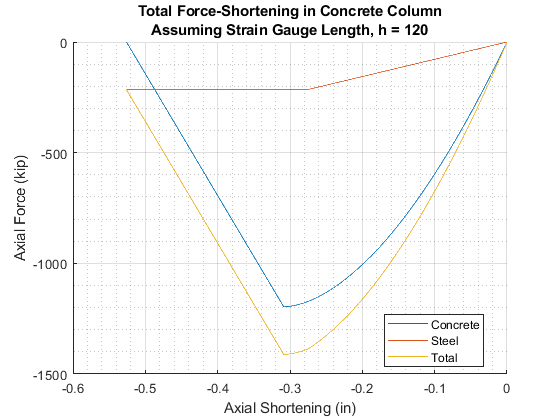

% With a single integration point
h = 120; % in
eta = 1/(1+0.04/(abs(fc_prime)/Ec*h));
max_ec = -fc_prime/eta/Ec + ec_prime;

% Concrete
pre_pk_concrete = @(e) -fc_prime*(1-(1-e/ec_prime).^nE);
post_pk_concrete = @(e) -eta*Ec*(e-ec_prime) - fc_prime;
f_concrete = @(e) (e <= ec_prime).*post_pk_concrete(e) + ~(e <= ec_prime).*pre_pk_concrete(e);
% Steel
f_steel = @(e) sign(e).*min(Es*abs(e),fy);

% Compute axial compressive force vs axial displacement
range = linspace(max_ec,0,1000);
concrete_axial_compression = Ac*f_concrete(range)/1000;
steel_axial_compression = As*f_steel(range)/1000;
Total_shortening1 = range*h;
Total_force1 = concrete_axial_compression + steel_axial_compression;

% Plotting
title = ["Total Force-Shortening in Concrete Column","Assuming Strain Gauge Length, h = 120"];
x = [Total_shortening1;Total_shortening1;Total_shortening1];
y = [concrete_axial_compression; steel_axial_compression; Total_force1];
names = ["Concrete"; "Steel"; "Total"];
print_plots(x, y, title, names, true)
print_figure("7")

### Part (ii) Using 3 Equal Integration Points

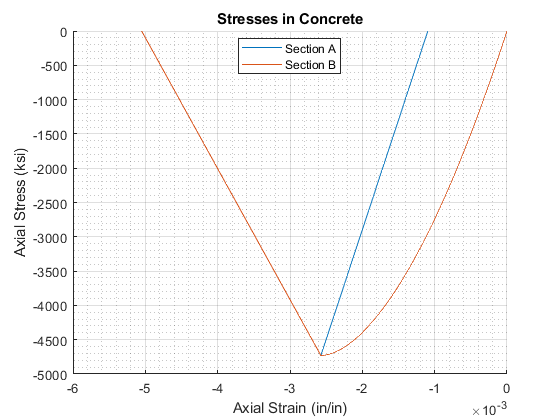

% With 3 equal Integration points
h = 40; 
eta = 1/(1+0.04/(fc_prime/Ec*h)); %
max_ec = -fc_prime/eta/Ec + ec_prime;

% Range for Analysis
pre_pk_range = linspace(0,ec_prime,500);
post_pk_range_A = linspace(ec_prime,ec_prime+fc_prime/Ec,50);
post_pk_range_B = linspace(ec_prime,max_ec,50);

% Concrete Stress-Strain Curve
pre_pk_concrete = @(e) -fc_prime*(1-(1-e/ec_prime).^nE); % Pre-peak formula
post_pk_concrete_A = @(e) Ec*(e-ec_prime) - fc_prime; % Post-peak formula
post_pk_concrete_B = @(e) -eta*Ec*(e-ec_prime) - fc_prime; % Post-peak formula

% Steel Stress-Strain Curve
f_steel_A = @(e) Es*(e -ec_prime) - fy;
f_steel_B = @(e) sign(e).*min(Es*abs(e),fy);

% Strain Ranges
Section_A_strain = [pre_pk_range, post_pk_range_A];
Section_B_strain = [pre_pk_range, post_pk_range_B];

% Stress Values
concrete_A_stress = [pre_pk_concrete(pre_pk_range), post_pk_concrete_A(post_pk_range_A)];
concrete_B_stress = [pre_pk_concrete(pre_pk_range), post_pk_concrete_B(post_pk_range_B)];
steel_A_stress = [f_steel_B(pre_pk_range), f_steel_A(post_pk_range_A)];
steel_B_stress = f_steel_B(Section_B_strain);

% Force Values
concrete_A_force = Ac/1000*concrete_A_stress; % kips
concrete_B_force = Ac/1000*concrete_B_stress; % kips
steel_A_force = As/1000* steel_A_stress; % kips
steel_B_force = As/1000* steel_B_stress; % kips

% Section compressive force
Section_A_force = concrete_A_force + steel_A_force;
Section_B_force = concrete_B_force + steel_B_force;

% Section shortening
Section_A_shorten = Section_A_strain * h;
Section_B_shorten = Section_B_strain * h;

% Total Column
Total_shortening2 = 2*Section_A_shorten + Section_B_shorten;
Total_force2 = Section_B_force;

% Plotting
title = "Stresses in Concrete";
x = [Section_A_strain;Section_B_strain];
y = [concrete_A_stress; concrete_B_stress];
names = ["Section A"; "Section B"];
print_plots(x, y, title, names, false)
print_figure("8_concrete")

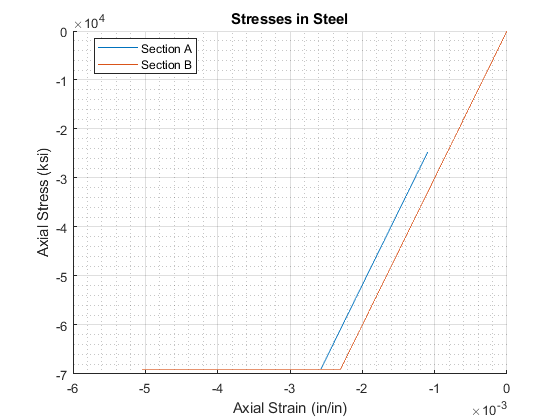


title = "Stresses in Steel";
x = [Section_A_strain;Section_B_strain];
y = [steel_A_stress; steel_B_stress];
names = ["Section A"; "Section B"];
print_plots(x, y, title, names, false)
print_figure("8_steel")

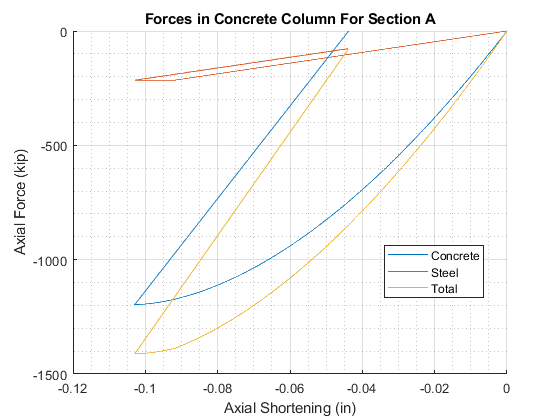

title = "Forces in Concrete Column For Section A";
x = [Section_A_shorten;Section_A_shorten;Section_A_shorten];
y = [concrete_A_force; steel_A_force; Section_A_force];
names = ["Concrete"; "Steel"; "Total"];
print_plots(x, y, title, names, true)
print_figure("8_forceA")

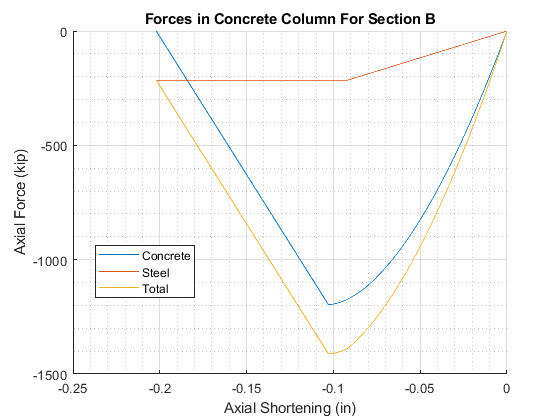

title = "Forces in Concrete Column For Section B";
x = [Section_B_shorten;Section_B_shorten;Section_B_shorten];
y = [concrete_B_force; steel_B_force; Section_B_force];
names = ["Concrete"; "Steel"; "Total"];
print_plots(x, y, title, names, true); ylim([-1500, 0])
print_figure("8_forceB")

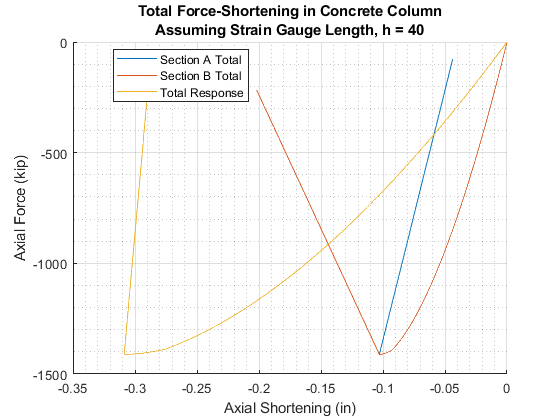

title = ["Total Force-Shortening in Concrete Column","Assuming Strain Gauge Length, h = 40"];
x = [Section_A_shorten;Section_B_shorten;Total_shortening2];
y = [Section_A_force; Section_B_force; Total_force2];
names = ["Section A Total"; "Section B Total"; "Total Response"];
print_plots(x, y, title, names, true)
print_figure("8_total")

## Question 2

Using Thorenfeldt's equation to model the entire stress-strain curve, pre and post peak responses. 

### Part (i) Using Single Integration Point

% With a single integration point
h = 120; % in
max_ec = -0.005;

% Thorenfeldt Eq. Parameters
n= nE/(nE-1)

n = 2.3141

n = Ec / (Ec + fc_prime/ec_prime)

n = 2.3502

k = 0.67  + fc_prime/9000

k = 1.1956

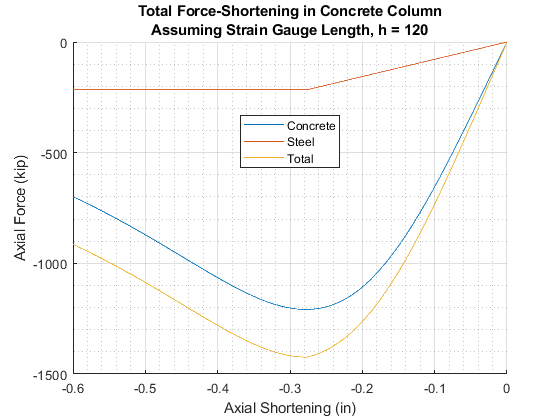

Thorenfeldt = @(e) -fc_prime*(n*(e/ec_prime))./(n-1+(e/ec_prime).^(n*k)); % Concrete
f_steel = @(e) sign(e).*min(Es*abs(e),fy); % Steel

% Compute axial compressive force vs axial displacement
range = linspace(0,max_ec,500);

% Stress values
concrete_stress = Thorenfeldt(range);
steel_stress = f_steel(range);

% Compression force
concrete_axial_compression = Ac/1000*concrete_stress;
steel_axial_compression = As/1000*steel_stress;
Total_force3 = concrete_axial_compression + steel_axial_compression;

% Shortening
Total_shortening3 = h * range;

% Plotting
title = ["Total Force-Shortening in Concrete Column","Assuming Strain Gauge Length, h = 120"];
x = [Total_shortening3;Total_shortening3;Total_shortening3];
y = [concrete_axial_compression; steel_axial_compression; Total_force3];
names = ["Concrete"; "Steel"; "Total"];
print_plots(x, y, title, names, true)
print_figure("9")

### Part (ii) Using Three Equal Integration Point

% With 3 equal Integration points
h = 40; 
max_ec = -0.005;

% Thorenfeldt Eq. Parameters
n = Ec / (Ec + fc_prime/ec_prime)

n = 2.3502

k = 0.67  + fc_prime/9000

k = 1.1956

% Concrete Stress-Strain Curve
Thorenfeldt = @(e) -fc_prime*(n*(e/ec_prime))./(n-1+(e/ec_prime).^(n*k)); % Concrete
post_pk_concrete_A = @(e) Ec*(e-ec_prime) - fc_prime; % Post-peak formula

% Steel Stress-Strain Curve
f_steel_A = @(e) Es*(e -ec_prime) - fy;
f_steel_B = @(e) sign(e).*min(Es*abs(e),fy);

% Range for Analysis
pre_pk_range = linspace(0,ec_prime,500);
post_pk_range_A = linspace(ec_prime,(fc_prime + Thorenfeldt(max_ec))/Ec + ec_prime,100);
post_pk_range_B = linspace(ec_prime,max_ec,100);

% Strain Ranges
Section_A_strain = [pre_pk_range, post_pk_range_A];
Section_B_strain = [pre_pk_range, post_pk_range_B];
Combined_strain = [3*pre_pk_range , 2*post_pk_range_A + post_pk_range_B];

% Stress Values
concrete_A_stress = [Thorenfeldt(pre_pk_range), post_pk_concrete_A(post_pk_range_A)];
concrete_B_stress = Thorenfeldt(Section_B_strain);
steel_A_stress = [f_steel_B(pre_pk_range), f_steel_A(post_pk_range_A)];
steel_B_stress = f_steel_B(Section_B_strain);

% Force Values
concrete_A_force = Ac/1000*concrete_A_stress; % kips
concrete_B_force = Ac/1000*concrete_B_stress; % kips
steel_A_force =    As/1000*steel_A_stress; % kips
steel_B_force =    As/1000*steel_B_stress; % kips

% Section compressive force
Section_A_force = concrete_A_force + steel_A_force;
Section_B_force = concrete_B_force + steel_B_force;

% Section shortening
Section_A_shorten = Section_A_strain* h; % *h
Section_B_shorten = Section_B_strain*h; % *h

% Total Responses
Total_force4 = Section_B_force;
Total_shortening4 = 2*Section_A_shorten + Section_B_shorten;

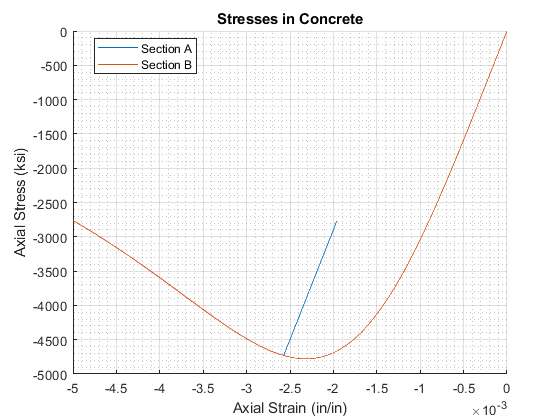

title = "Stresses in Concrete";
x = [Section_A_strain;Section_B_strain];
y = [concrete_A_stress; concrete_B_stress];
names = ["Section A"; "Section B"];
print_plots(x, y, title, names, false)
print_figure("9_concrete")

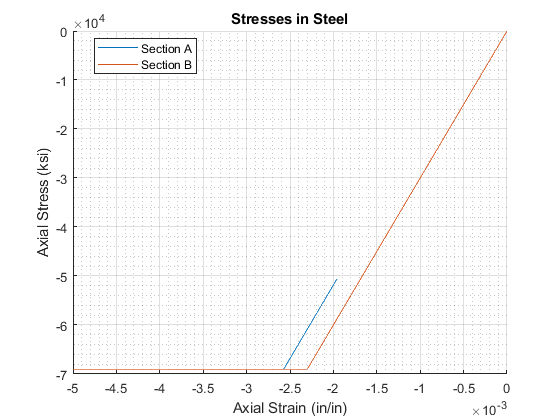

title = "Stresses in Steel";
x = [Section_A_strain;Section_B_strain];
y = [steel_A_stress; steel_B_stress];
names = ["Section A"; "Section B"];
print_plots(x, y, title, names, false)
print_figure("9_steel")

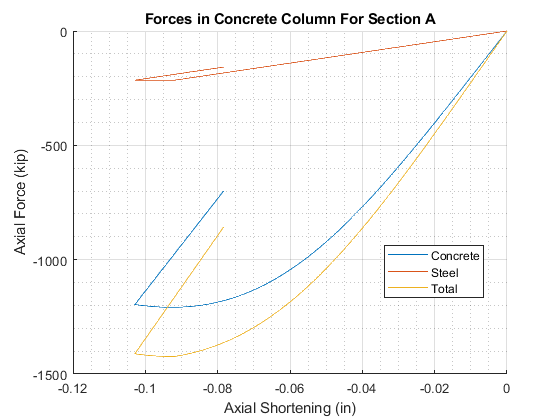

title = "Forces in Concrete Column For Section A";
x = [Section_A_shorten;Section_A_shorten;Section_A_shorten];
y = [concrete_A_force; steel_A_force; Section_A_force];
names = ["Concrete"; "Steel"; "Total"];
print_plots(x, y, title, names, true)
print_figure("9_forceA")

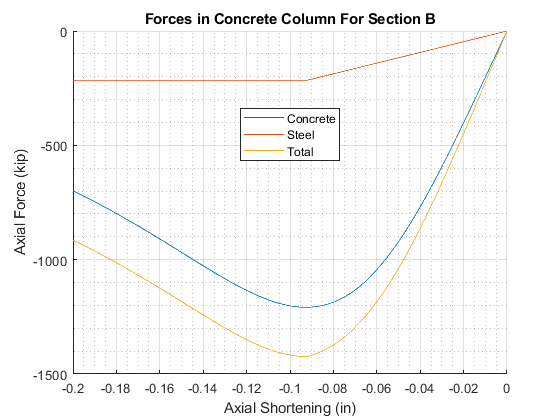

title = "Forces in Concrete Column For Section B";
x = [Section_B_shorten;Section_B_shorten;Section_B_shorten];
y = [concrete_B_force; steel_B_force; Section_B_force];
names = ["Concrete"; "Steel"; "Total"];
print_plots(x, y, title, names, true)
print_figure("9_forceB")

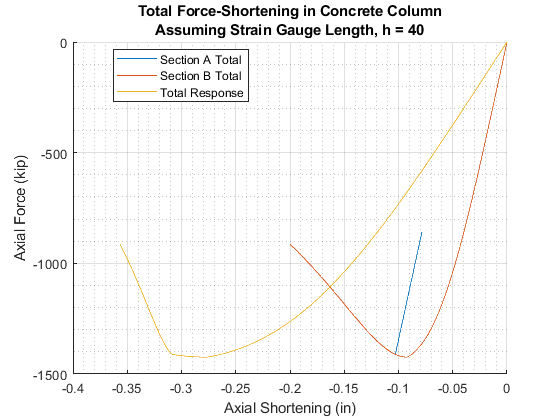

title = ["Total Force-Shortening in Concrete Column","Assuming Strain Gauge Length, h = 40"];
x = [Section_A_shorten;Section_B_shorten;Total_shortening4];
y = [Section_A_force; Section_B_force; Total_force4];
names = ["Section A Total"; "Section B Total"; "Total Response"];
print_plots(x, y, title, names, true)
print_figure("9_total")

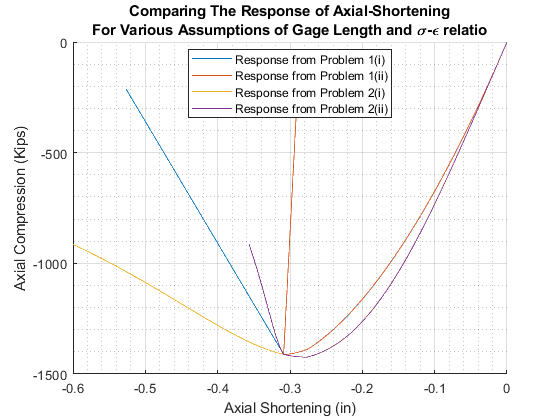

close all; figure; axis on; grid minor; grid on; hold on; legend('Location',"Best"); clear title;
title(["Comparing The Response of Axial-Shortening","For Various Assumptions of Gage Length and \sigma-\epsilon relatio"]);
ylabel("Axial Compression (Kips)"); xlabel(['Axial Shorte' ...
    'ning (in)']);
plot(Total_shortening1,Total_force1,"DisplayName","Response from Problem 1(i)");
plot(Total_shortening2,Total_force2,"DisplayName","Response from Problem 1(ii)");
plot(Total_shortening3,Total_force3,"DisplayName","Response from Problem 2(i)");
plot(Total_shortening4,Total_force4,"DisplayName","Response from Problem 2(ii)");
print_figure("10")

function print_figure(no)
    % Saves the figures in a consistent manner
    orient(gcf,'landscape');
    folder = '..\figures\';
    name = 'Figure' +string(no);
    print(folder+name,'-dpdf','-fillpage','-PMicrosoft Print to PDF','-r600','-painters')
    
end

function print_plots(x, y, title_, name, plot_forces)
    figure(); hold on; grid on; grid minor;
    legend('Location',"Best"); title(title_); 
    for j = 1:size(x,1)
        plot(x(j,:), y(j,:), "DisplayName",name(j))
    end
    if plot_forces
        ylabel("Axial Force (kip)"); xlabel('Axial Shortening (in)');
%         ylim([-1600 0])
    else 
        ylabel("Axial Stress (ksi)"); xlabel('Axial Strain (in/in)');
%         ylim([-5000 0])
    end
end